clear
clc
close all

PID

P = tf([0 0 0 1], [1 6 5 0])

P =
 
          1
  -----------------
  s^3 + 6 s^2 + 5 s
 
Continuous-time transfer function.



Kp = 39.42;
Ti = 3.077;
Td = 0.7692;
C = tf([Kp*Td Kp Kp/Ti], [0 1 0])

C =
 
  30.32 s^2 + 39.42 s + 12.81
  ---------------------------
               s
 
Continuous-time transfer function.



Hc = feedback(C*P,1)

Hc =
 
         30.32 s^2 + 39.42 s + 12.81
  -----------------------------------------
  s^4 + 6 s^3 + 35.32 s^2 + 39.42 s + 12.81
 
Continuous-time transfer function.



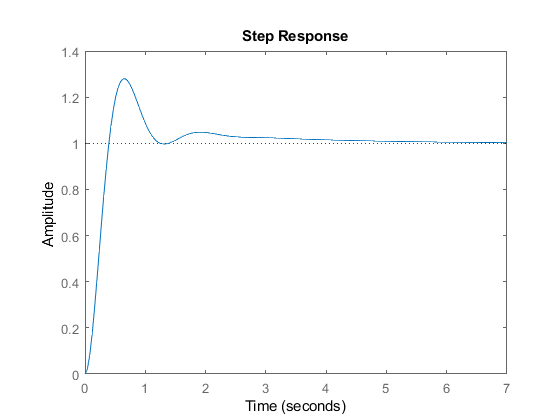

step(Hc);

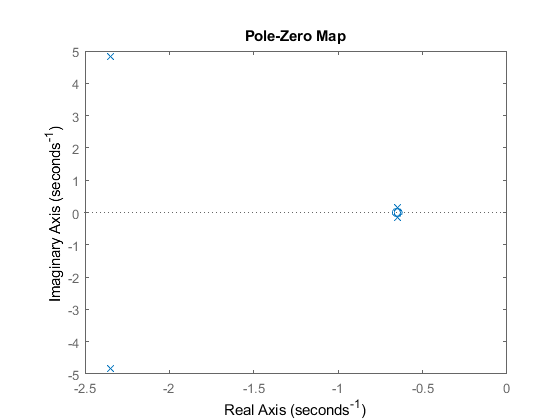

pzmap(Hc)

Controlador I-PD

Gd = tf([Td 1], 1)

Gd =
 
  0.7692 s + 1
 
Continuous-time transfer function.



Gp = tf(Kp,1)

Gp =
 
  39.42
 
Static gain.



HcPD = feedback(Gp*P,Gd)

HcPD =
 
              39.42
  -----------------------------
  s^3 + 6 s^2 + 35.32 s + 39.42
 
Continuous-time transfer function.



Gi = tf([0 1], [Ti 0])

Gi =
 
     1
  -------
  3.077 s
 
Continuous-time transfer function.



HcIPD = feedback(Gi*HcPD,1)

HcIPD =
 
                         39.42
  ---------------------------------------------------
  3.077 s^4 + 18.46 s^3 + 108.7 s^2 + 121.3 s + 39.42
 
Continuous-time transfer function.



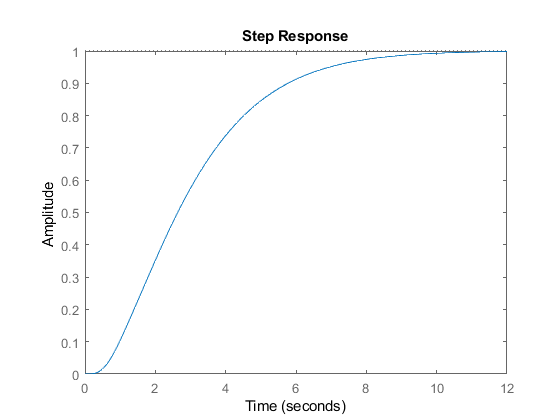

step(HcIPD)

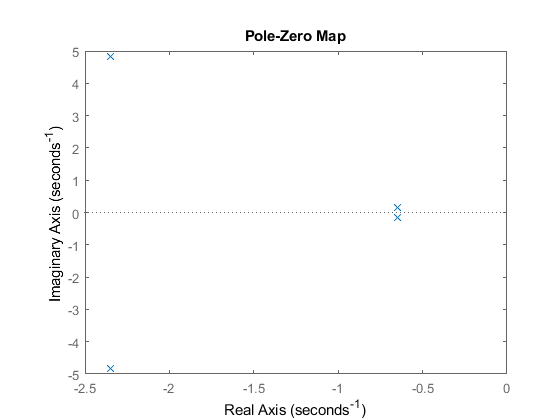

pzmap(HcIPD)